# 航天飞行器动力学原理 第四周作业

# ——考虑J2项的轨道摄动计算

## 给定各常数及初始条件

mu = 398603e09; 
Vx = 5.3e03; Vy = 0.2e03; Vz = 2e03; %示例采用xoy平面内的第一宇宙速度近地轨道
Rx = 0; Ry = 2.0*6.371e06; Rz = 0;%均为惯性坐标系下的投影分量，采用国际单位制
V0 = [Vx;Vy;Vz]

V0 =         5300
         200
        2000


R0 = [Rx;Ry;Rz] %列向量

R0 =            0
    12742000
           0


## 将初始速度与坐标分量转换为轨道根数

[a0,e0,theta0,Omega0,i0,omega0] = pro2orb(V0,R0) %pro2ob()函数为自定义的函数，见pro2orb.mlx文件

a0 = 1.3097e+07

e0 = 0.0445

theta0 = 0.9516

Omega0 = 1.5708

i0 = 2.7808

omega0 = 5.3315

p0 = a0*(1-e0^2);
u0 = omega0+theta0;

## 计算对应的轨道根数并转换为投影

tic
[t,p,e,Omega,i,u,theta] = predict_J2(0:10:900000,p0,e0,Omega0,i0,u0,theta0);
a = p./(1-e0.^2);
omega = u - theta;
[V,R] = orb2pro(a,e,theta,Omega,i,omega);
toc

历时 1.072950 秒。


## 绘制地球与卫星的相对位置

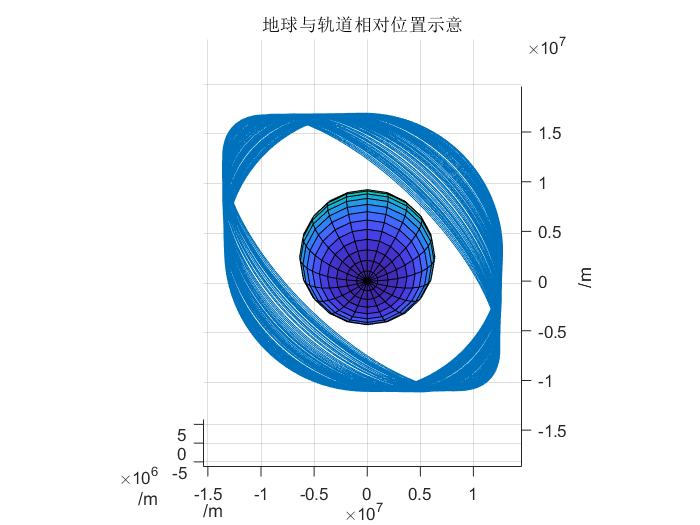

figure
hold on
plot3(R(1,:),R(2,:),R(3,:));
ellipsoid(0,0,0,6.371e06,6.371e06,6.371e06);
view(cross(R(:,1),V(:,1)))
axis equal
grid on
title('地球与轨道相对位置示意')
xlabel('/m');
ylabel('/m');
zlabel('/m');
hold off